num=[7.4 24.64];
tdead=0.5;
den=[1.46e-5 0.00168 0.05738 0.556 1 0];
G=tf(num,den)

G =
 
                       7.4 s + 24.64
  --------------------------------------------------------
  1.46e-05 s^5 + 0.00168 s^4 + 0.05738 s^3 + 0.556 s^2 + s
 
Continuous-time transfer function.



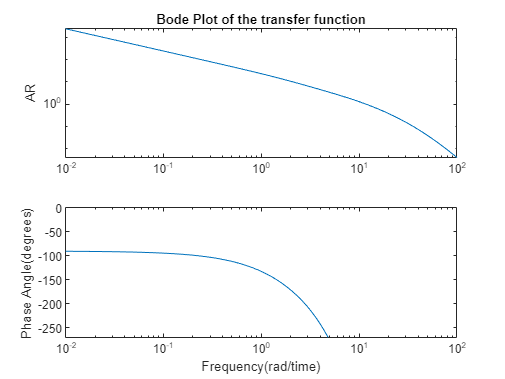


points =500;
ww=logspace(-2,2,points);
[mag,phase,ww]=bode(G,ww);

AR=zeros(points,1);
PA=zeros(points,1);

for i=1:points
    AR(i)=mag(1,1,i);
    PA(i)=phase(1,1,i)-((180/pi)*tdead*ww(i));
end
figure
subplot(2,1,1)
loglog(ww,AR)
title('Bode Plot of the transfer function')

%axis([0.01 100 .001 25])
ylabel('AR')
subplot(2,1,2)
semilogx(ww,PA)
axis([0.01 100 -270 0])
ylabel('Phase Angle(degrees)')
xlabel('Frequency(rad/time)')